Quick interactive tutorial on using Daubechies' wavelets for eigenvalue problems. **[Example]**

Solves for eigenvalues of a 1D Triangular Well.


$$-\frac{1}{2}\cdot\frac{d^2f(x)}{dx^2} + |x| { = Ef(x)$$


Compare with: [https://www.nextnano.com/nextnano3/tutorial/1Dtutorial_GaAs_triangular_well.htm](https://www.nextnano.com/nextnano3/tutorial/1Dtutorial_GaAs_triangular_well.htm)

[ws,x] = wpfun('db3',1,10); %inspect w, x in the workspace tab!
W = ws(2,:); %mother wavelet
S = ws(1,:); %mother scaling function

Constructing a basis set {S, W}. 

basis = [];
for n = (-2:2) + 2.5
    basis = [basis; DT(S,x,1,n)];
end
for n = (-2:2) + 2.5
    basis = [basis; DT(W,x,1,n)];
end

[~, x] = DT(S, x, 1, 0);
sz = size(basis); sz = sz(1);



Visualizing the problem.

- 
$$-\frac{1}{2}\cdot\frac{d^2f(x)}{dx^2} + |x - 2.5| { = Ef(x)$$


- 
$$f(x) \equiv s_n^k , w_n^k$$


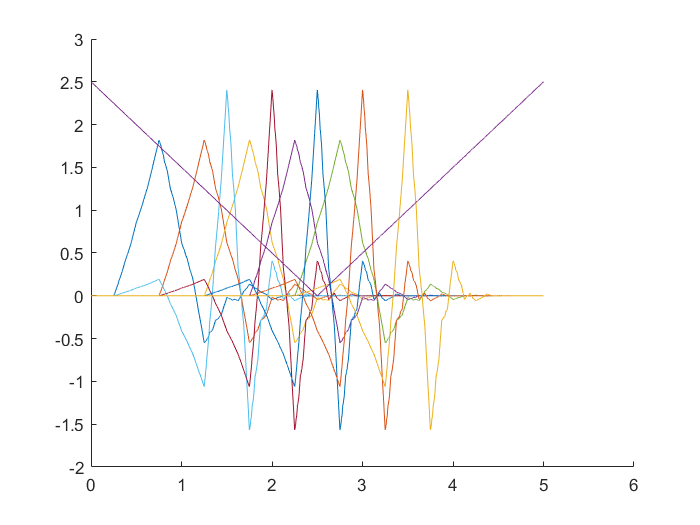

figure(1)
clf 
hold on
for k = 1:sz
plot(x, basis(k,:));
end
plot(x, abs(x-2.5))
hold off

- Everything is zero outside [0, 2K - 1] = [0, 5].

- Wavelets are evenly distributed on either side of the well's centre.

Constructing the Hamiltonian.

- H includes (s,s), (s,w), (w,s), (w,w) overlaps.

- Theres a division by 2^1 because our lowest k = 1

H = zeros([sz sz]); T = zeros([sz sz]); V = zeros([sz sz]);

for i = 1:sz
    for j = i:sz
        T(i, j) = 0.5 * trapz(singlediff(basis(i,:),x) .* singlediff(basis(j,:),x)) * x(2);
        V(i, j) = trapz(basis(i,:) .* abs(x-2.5) .* basis(j,:)) * x(2);
    end
end
H = T + V;
H = H + H' - diag(diag(H)); 
H=H/2 

H =     6.1172   -3.3456    0.8638   -0.1131   -0.0053    2.8109   -1.6635    0.1394   -0.0091   -0.0006
   -3.3456    5.8673   -3.3396    0.8637   -0.1130    0.2907    2.8109   -1.6662    0.1394   -0.0091
    0.8638   -3.3396    5.6177   -3.3479    0.8729   -2.9327    0.2967    2.8048   -1.6694    0.1402
   -0.1131    0.8637   -3.3479    5.3818   -3.3959    1.3225   -2.9316    0.3171    2.7880   -1.6758
   -0.0053   -0.1130    0.8729   -3.3959    5.3823    0.0495    1.3220   -3.0175    0.4170    2.7671
    2.8109    0.2907   -2.9327    1.3225    0.0495   37.0933   10.2642   -0.9054    0.1131    0.0053
   -1.6635    2.8109    0.2967   -2.9316    1.3220   10.2642   36.8436   10.2383   -0.9049    0.1130
    0.1394   -1.6662    2.8048    0.3171   -3.0175   -0.9054   10.2383   36.6676   10.3212   -0.9165
   -0.0091    0.1394   -1.6694    2.7880    0.4170    0.1131   -0.9049   10.3212   36.8460   10.3342
   -0.0006   -0.0091    0.1402   -1.6758    2.7671    0.0053    0.1130   -0.9165   10.3

Eigenvalues and eigenfunctions

- Look at MATLAB documentation for *eig*

- It furnishes eigenvectors, eigenvalues in [v, d] for inputted matrix.

[v,d] = eig(H);
clf
fprintf('Numerical: %1.3f', min(diag(d)));

Numerical: 0.688

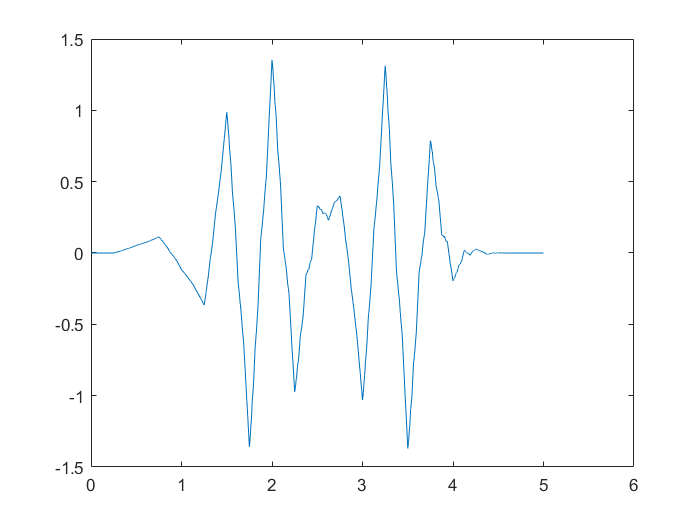

f =(v(:,end-1)' * basis);
figure(2)
plot(x,f)

Utility functions to scale, translate, and differentiate. 

function [DTw, DTx] = DT(w,x,k,n)
    %changes w00 to wkn
    %keep n <= (2K - 1)(2^k - 1)
    DTw = w;
    DTx = x+n;
    
    DTw = 2^(k/2)*DTw;
    DTx = DTx/(2^k);
    
    newxstep = DTx(2) - DTx(1);
    Lpad = round(DTx(1) / newxstep);
    
    DTx = wextend('1', 'asymw', DTx, length(DTx)*(2^k - 1), 'r');
    
    DTw = [DTw , zeros(1,(length(DTx) - length(DTw)))];
    DTw = circshift(DTw, Lpad); DTw(1:Lpad) = zeros(1, Lpad);   
    DTx = wextend('1', 'asymw', DTx, Lpad, 'l');
    
    DTx = DTx(1:length(DTw));
    
end

function [wd, xd] = singlediff(w, x)
    wd = gradient(w)/(x(2) - x(1));
    xd = x;
end

function [wdd, xdd] = doublediff(w, x)
    wd = gradient(w)/(x(2) - x(1));
    wdd = gradient(wd)/(x(2) - x(1));
    xdd = x;
end

function v = Vwell(x, y)
    if x >= 4.5*.5 && x <= 4.5*1.5 && y >= 4.5*.5 && y <= 4.5*1.5
        v = 0;
    else
        v = 100;
    end
end